# FIRST TRY SPECTRAL BASED ANALYSIS

listDirs = uigetdirs;

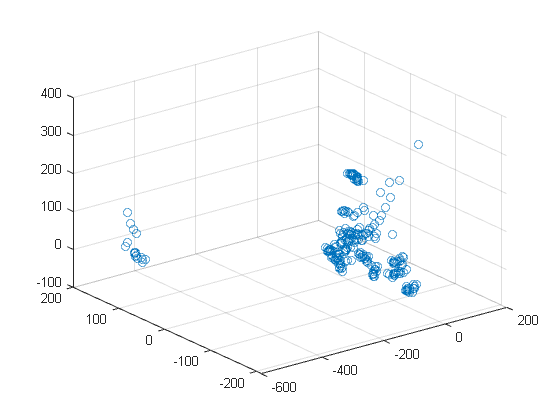


load(fullfile(listDirs{1}, 'Dataset2', 'infoDataset.mat'));
dev_Spectra = infoDataset.AdditionalInformation.getDerivatives.dev_spectra(:, [1, 4]);
dev_profile1 = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 5]);
dev_profile2 = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 8]);

for ii = 2:numel(listDirs)

    load(fullfile(listDirs{ii}, 'Dataset2', 'infoDataset.mat'));

    XY = infoDataset.AdditionalInformation.getDerivatives.dev_spectra(:, [1, 4]);
    vq = interp1(XY(:,1 ), XY(:, 2), dev_Spectra(:, 1));
    dev_Spectra(:, end+1) = vq;
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 5]);
    vq = interp1(XY(:,1 ), XY(:, 2), dev_profile1(:, 1));
    dev_profile1(:, end+1) = vq;
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 8]);
    vq = interp1(XY(:,1 ), XY(:, 2), dev_profile2(:, 1));
    dev_profile2(:, end+1) = vq;

end


dev_Spectra(sum(isnan(dev_Spectra)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_Spectra(:, 2:end)','VariableWeights','variance');
h = scatter3(score(:, 1), score(:, 2), score(:, 3));

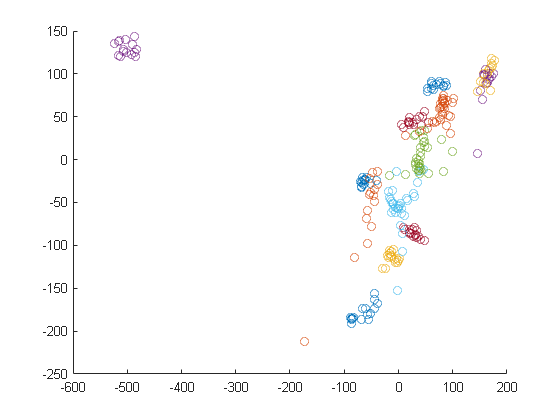

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

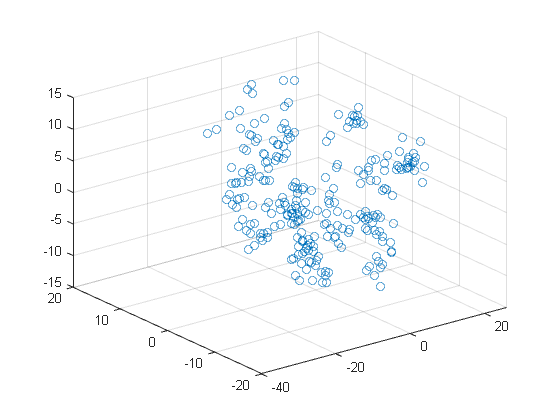


dev_profile1(sum(isnan(dev_profile1)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_profile1(:, 2:end)','VariableWeights','variance');
h = scatter3(score(:, 1), score(:, 2), score(:, 3));

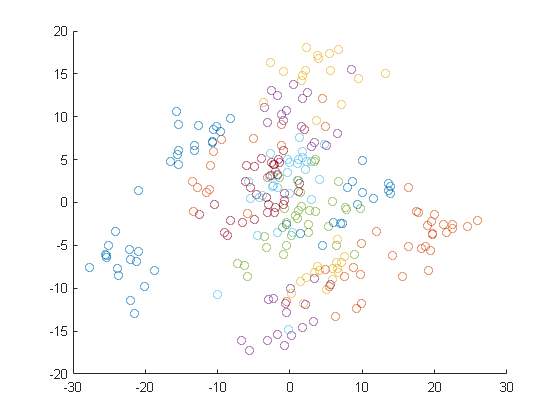

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

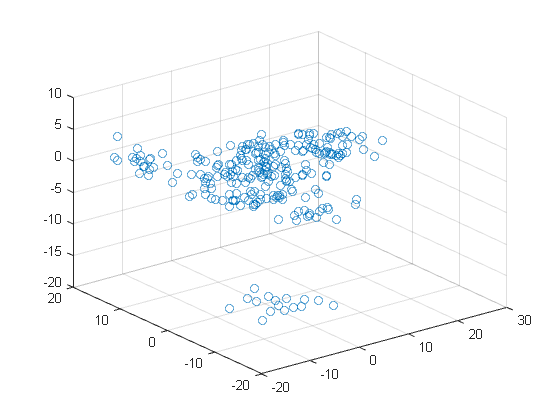


dev_profile2(sum(isnan(dev_profile2)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_profile2(:, 2:end)','VariableWeights','variance');
h = scatter3(score(:, 1), score(:, 2), score(:, 3));

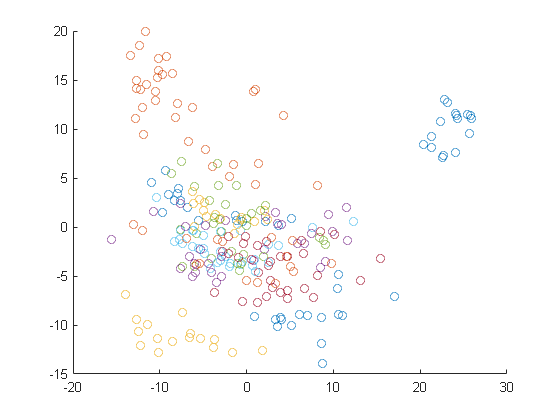

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

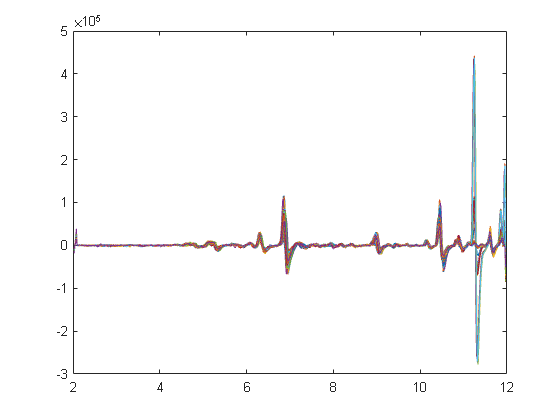


plot(dev_profile1(:, 1), dev_profile1(:, 2:end))

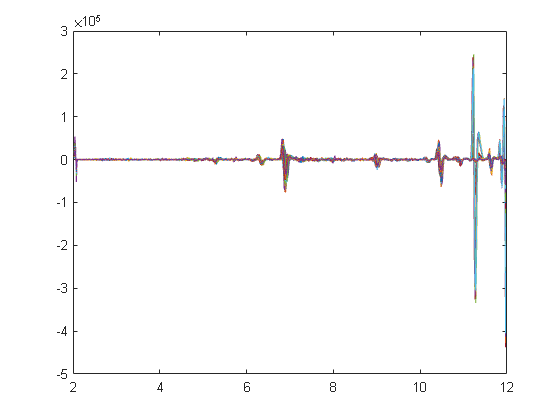

plot(dev_profile2(:, 1), dev_profile2(:, 2:end))

## Full alignemnts



firstOne = [];
secondOne = [];
thirdOne = []; 
Range = 0.01;
minSize = 200;
Dmz = 0.01; % mz
Dtm = 0.1; % tm
allClusters = {};

for ii = 1:numel(listDirs)

    load(fullfile(listDirs{ii}, 'Dataset2', 'infoDataset.mat'));
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 3, 4]);
    LM = LocalMaxima(XY(:, [1, 2]), 3, 0);
    LM(LM(:, 2) < Range*max(LM(:, 2)), :) = [];
    for jj = 1:numel(LM(:, 1))
        LM(jj, 3) = XY(findCloser(LM(jj, 1), XY(:, 1)), 3);
    end
    LM(:, 4) = ii;
    firstOne = [firstOne; LM];
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 6, 7]);
    LM = LocalMaxima(XY(:, [1, 2]), 3, 0);
    LM(LM(:, 2) < Range*max(LM(:, 2)), :) = [];
    for jj = 1:numel(LM(:, 1))
        LM(jj, 3) = XY(findCloser(LM(jj, 1), XY(:, 1)), 3);
    end
    LM(:, 4) = ii;
    secondOne = [secondOne; LM];

    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 9, 10]);
    LM = LocalMaxima(XY(:, [1, 2]), 3, 0);
    LM(LM(:, 2) < Range*max(LM(:, 2)), :) = [];
    for jj = 1:numel(LM(:, 1))
        LM(jj, 3) = XY(findCloser(LM(jj, 1), XY(:, 1)), 3);
    end
    LM(:, 4) = ii;
    thirdOne = [thirdOne; LM];

end

% Do the first one
firstOne = sortrows(firstOne, 3);
firstOne(2:end, 5) = (firstOne(2:end, 3) - firstOne(1:end-1, 3)) > Dmz;
fCluster = {};
while 1
    Id = find(firstOne(:, 5) == 1, 1, "first");
    if isempty(Id)
        fCluster{end+1} = firstOne;
        break

    end
    fCluster{end+1} = firstOne(1:Id-1, :);
    firstOne(1:Id-1, :) = [];
    if isempty(firstOne), break; end
    firstOne(1, 5) = 0;

end

gCluster = {};
for ii = 1:numel(fCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 1);
    XY(2:end, 5) = (XY(2:end, 3) - XY(1:end-1, 3)) > Dtm;


    while 1
        Id = find(XY(:, 5) == 1, 1, "first");
        if isempty(Id)
            gCluster{end+1} = XY;
            break

        end
        gCluster{end+1} = XY(1:Id-1, :);
        XY(1:Id-1, :) = [];
        if isempty(XY), break; end
        XY(1, 5) = 0;

    end
end

for ii = 1:numel(gCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 4);

    if height(XY) >= minSize & numel(XY(:, 4)) == numel(unique(XY(:, 4)))
        allClusters{end+1} = XY;

    end
end

% Do the second one
secondOne = sortrows(secondOne, 3);
secondOne(2:end, 5) = (secondOne(2:end, 3) - secondOne(1:end-1, 3)) > Dmz;
fCluster = {};
while 1
    Id = find(secondOne(:, 5) == 1, 1, "first");
    if isempty(Id)
        fCluster{end+1} = secondOne;
        break

    end
    fCluster{end+1} = secondOne(1:Id-1, :);
    secondOne(1:Id-1, :) = [];
    if isempty(secondOne), break; end
    secondOne(1, 5) = 0;

end

gCluster = {};
for ii = 1:numel(fCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 1);
    XY(2:end, 5) = (XY(2:end, 3) - XY(1:end-1, 3)) > Dtm;


    while 1
        Id = find(XY(:, 5) == 1, 1, "first");
        if isempty(Id)
            gCluster{end+1} = XY;
            break

        end
        gCluster{end+1} = XY(1:Id-1, :);
        XY(1:Id-1, :) = [];
        if isempty(XY), break; end
        XY(1, 5) = 0;

    end
end

for ii = 1:numel(gCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 4);

    if height(XY) >= minSize & numel(XY(:, 4)) == numel(unique(XY(:, 4)))
        allClusters{end+1} = XY;

    end
end

% Do the third one
thirdOne = sortrows(thirdOne, 3);
thirdOne(2:end, 5) = (thirdOne(2:end, 3) - thirdOne(1:end-1, 3)) > Dmz;
fCluster = {};
while 1
    Id = find(thirdOne(:, 5) == 1, 1, "first");
    if isempty(Id)
        fCluster{end+1} = thirdOne;
        break

    end
    fCluster{end+1} = thirdOne(1:Id-1, :);
    thirdOne(1:Id-1, :) = [];
    if isempty(thirdOne), break; end
    thirdOne(1, 5) = 0;

end

gCluster = {};
for ii = 1:numel(fCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 1);
    XY(2:end, 5) = (XY(2:end, 3) - XY(1:end-1, 3)) > Dtm;


    while 1
        Id = find(XY(:, 5) == 1, 1, "first");
        if isempty(Id)
            gCluster{end+1} = XY;
            break

        end
        gCluster{end+1} = XY(1:Id-1, :);
        XY(1:Id-1, :) = [];
        if isempty(XY), break; end
        XY(1, 5) = 0;

    end
end

for ii = 1:numel(gCluster)
    XY = fCluster{ii};
    XY = sortrows(XY, 4);

    if height(XY) >= minSize & numel(XY(:, 4)) == numel(unique(XY(:, 4)))
        allClusters{end+1} = XY;

    end
end

myMatrix = nan(numel(allClusters), 257);
for ii = 1:numel(allClusters)
    XY = allClusters{ii};
    myMatrix(ii, 1) = mean(XY(:, 1));
    myMatrix(ii, XY(:, 4)+1) = XY(:, 1);

end

for ii = 1:256
    XY = [myMatrix(:, ii+1), myMatrix(:,1)-myMatrix(:,ii+1)];
    XY(sum(isnan(XY(:, 2)) ,2) >0, :) = [];
    [p, S, mu] = polyfit(XY(:,1), XY(:,2), 2);
    P{ii} = {p, S, mu};

end


## After corrections

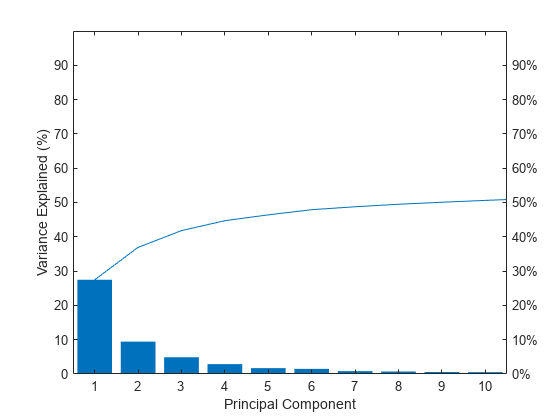



load(fullfile(listDirs{1}, 'Dataset2', 'infoDataset.mat'));
dev_Spectra = infoDataset.AdditionalInformation.getDerivatives.dev_spectra(:, [1, 4]);
dev_profile1 = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 5]);
dev_profile1(:, 1) = dev_profile1(:, 1) + polyval(P{1}{1}, dev_profile1(:, 1), P{1}{2}, P{1}{3});
dev_profile2 = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 8]);
dev_profile2(:, 1) = dev_profile2(:, 1) + polyval(P{1}{1}, dev_profile2(:, 1), P{1}{2}, P{1}{3});

for ii = 2:numel(listDirs)

    load(fullfile(listDirs{ii}, 'Dataset2', 'infoDataset.mat'));

    XY = infoDataset.AdditionalInformation.getDerivatives.dev_spectra(:, [1, 4]);
    vq = interp1(XY(:,1 ), XY(:, 2), dev_Spectra(:, 1));
    dev_Spectra(:, end+1) = vq;
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 5]);
    XY(:, 1) = XY(:, 1) + polyval(P{ii}{1}, XY(:, 1), P{ii}{2}, P{ii}{3});
    vq = interp1(XY(:,1 ), XY(:, 2), dev_profile1(:, 1));
    dev_profile1(:, end+1) = vq;
    
    XY = infoDataset.AdditionalInformation.getDerivatives.dev_profiles(:, [1, 8]);
    XY(:, 1) = XY(:, 1) + polyval(P{ii}{1}, XY(:, 1), P{ii}{2}, P{ii}{3});
    vq = interp1(XY(:,1 ), XY(:, 2), dev_profile2(:, 1));
    dev_profile2(:, end+1) = vq;

end


dev_Spectra(sum(isnan(dev_Spectra)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_Spectra(:, 2:end)','VariableWeights','variance');
figure
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

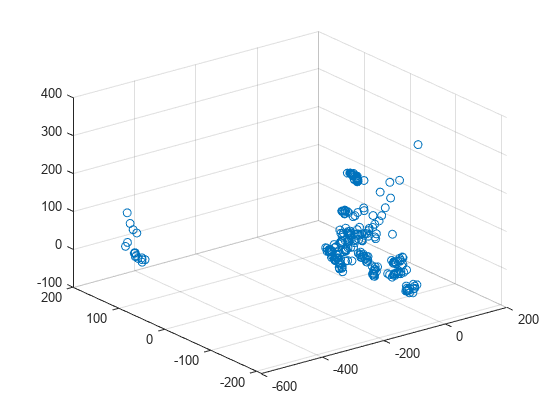


h = scatter3(score(:, 1), score(:, 2), score(:, 3));

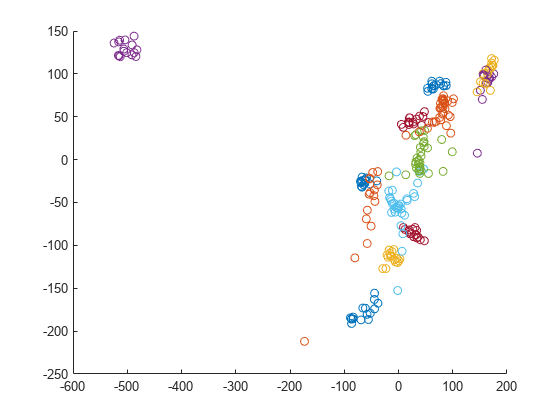

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

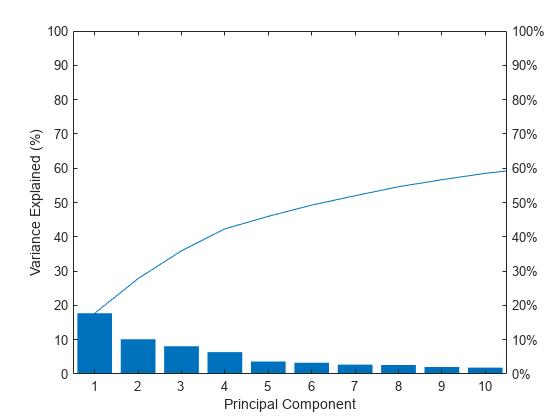


dev_profile1(sum(isnan(dev_profile1)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_profile1(:, 2:end)','VariableWeights','variance');
figure
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

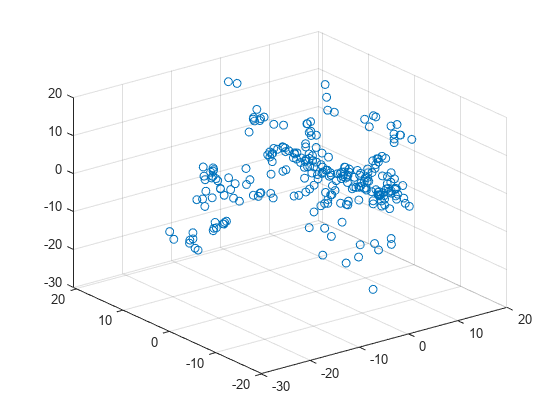


h = scatter3(score(:, 1), score(:, 2), score(:, 3));

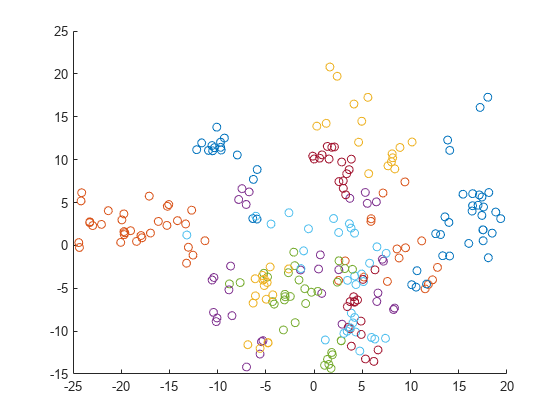

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

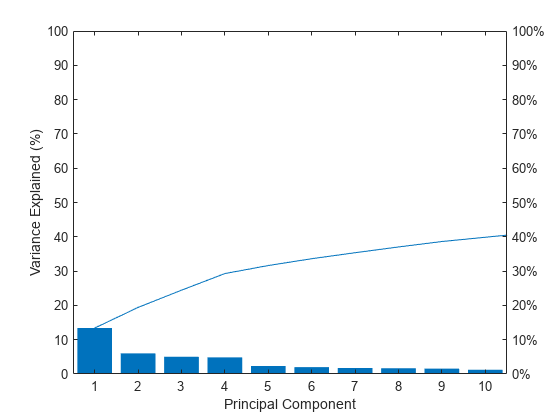


dev_profile2(sum(isnan(dev_profile2)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_profile2(:, 2:end)','VariableWeights','variance');
figure
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

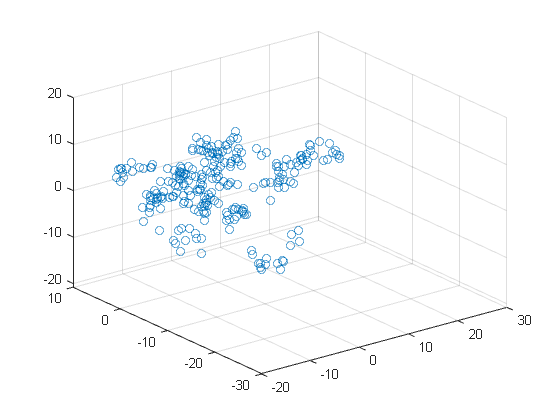


h = scatter3(score(:, 1), score(:, 2), score(:, 3));

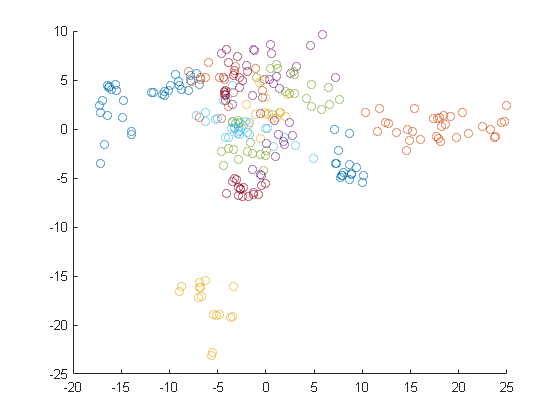

figure, hold on
for ii = 1:16
    scatter3(score(myMap.Code == ii, 1), score(myMap.Code == ii, 2), score(myMap.Code == ii, 3));

end
hold off

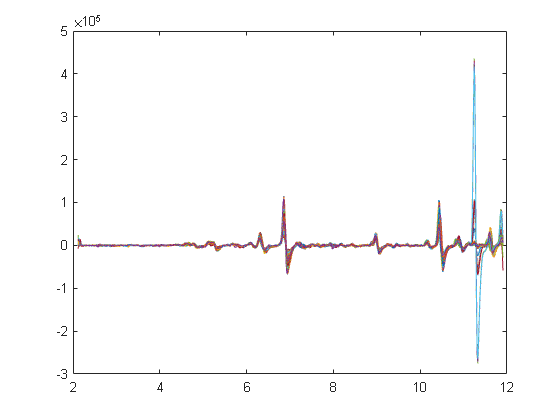


plot(dev_profile1(:, 1), dev_profile1(:, 2:end))

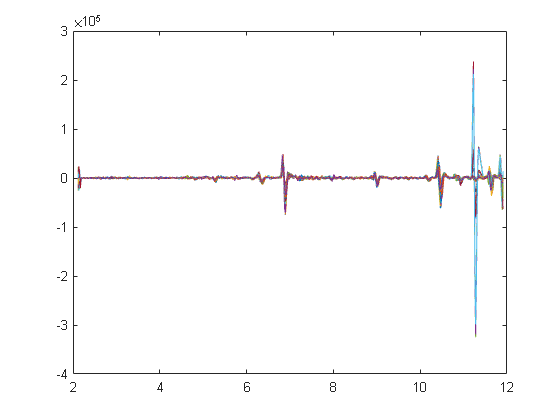

plot(dev_profile2(:, 1), dev_profile2(:, 2:end))

## PCA^2

dev_Spectra(sum(isnan(dev_Spectra)')' > 0, :) = [];
[wcoeff,score,latent,tsquared,explained] = pca(dev_Spectra(:, 2:end)','VariableWeights','variance');
figure
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

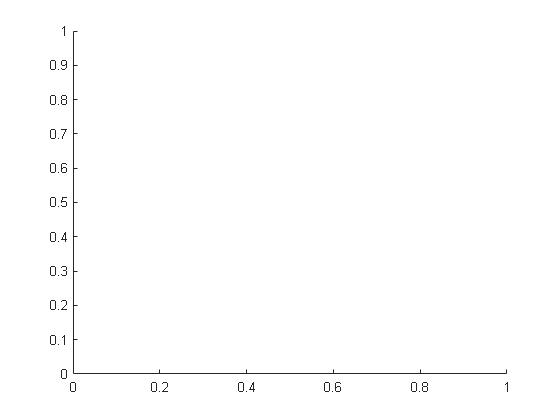


figure, nexttile

## AND RECORD!

% for ii = 1:numel(listDirs)
%     [filepath,name,ext] = fileparts(listDirs{ii});
%     IdF = find(strcmp(myProject.Summary.FileID, name));
%     myProject.Summary.AlignMe{IdF} = P{ii};
% 
% end
% 
% save(fullfile(myProject.Path2Project, 'myProject.mat'), 'myProject')
% 